# Animación Respuesta a Excitación Sísmica Edificio con Control

## Simulación

Parámetros de la estructura:

clear
m = [6 5 4]; %masas
b = [0.08 0.05 0.04]; %coeficientes de amortiguamiento
k = [5000 4800 5100]; %coeficientes de rigidez

r_theta = [1 1 1]; %vector de posición de actuadores hidráulicos

alpha = 1; omega = 14.6165; %amplitud y frecuencia de la excitación sísmica

r = @(a,w,t) a.*sin(w.*t); %excitación sísmica
t_int = 0:0.001:500; %periodo de simulación

mbkd = [0.5 0.06 4500]; %parámetros de la masas de amortiguamiento activo
%mbkd = [0]; %simulación sin masa de amortiguamiento activa


g_bar = gamma_bar(length(m));
theta = MM(r_theta);

if mbkd(1) == 0 % en el caso de control sin masa de amortiguamiento activo
    gamma = g_bar*theta;
    B = BK(b);
    delta = -1*m';
    K = BK(k);
    M = MM(m);
else % en el caso de control con masa de amortiguamiento activo
    gamma = gamma_AMD(g_bar*theta);
    B = BK_AMD(BK(b),mbkd(2));
    delta = -1*[m mbkd(1)]';
    K = BK_AMD(BK(k),mbkd(3));
    M = MM_AMD(MM(m),mbkd(1));
end

n = length(M);

Construcción del modelo en espacio de estados:

A = [zeros(n) eye(n); -inv(M)*K -inv(M)*B];
Bu = [zeros(n); M\gamma];
Br =  [zeros(n);MM(M\delta)];
C = [eye(n) zeros(n)];
D = zeros(n);

Obtención de la Matriz G de control:

Q = eye(n*2);
R = eye(n);
G = lqr(A, Bu, Q, R);

A_c = A-Bu*G;
sys = ss(A_c, [zeros(n,1);inv(M)*delta], C, zeros(n,1));

Simulación del movimiento lateral:

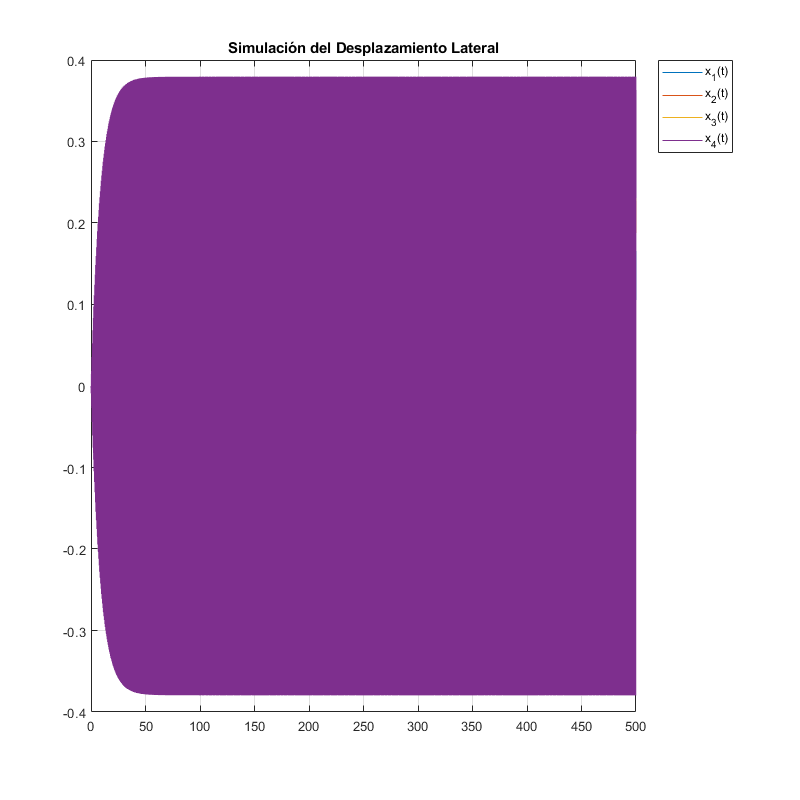

labels = cell(1,n);
for i = 1:n
    labels{1,i} = sprintf("x_%d(t)", i);
end
figure('Position', [100, 100, 1200, 1200])
[y, tOut, ~] = lsim(sys, r(alpha, omega, t_int), t_int);
plot(tOut, y)
grid on
title("Simulación del Desplazamiento Lateral")
legend(labels, "Location", "bestoutside")

fprintf("Tamaño de t_int: %d", size(t_int))

Tamaño de t_int: 1Tamaño de t_int: 500001

## Calibración de Visualización de Animación

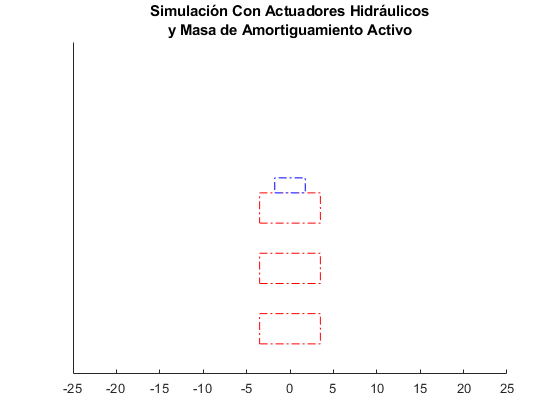

figure
sep = 0.15; %separación entre cada recuadro 
height = 0.15; %altura de cada recuadro
width = 7; %anchura de cada recuadro
pos = y'; %posiciones resultantes de la simulación
max_height = 1.5; %limite en el eje y
min_height = -0.15; %limite negativo en el eje y
xlim = 25; %limite en el eje x

simTitle = ["Simulación Con Actuadores Hidráulicos" "y Masa de Amortiguamiento Activo"];

for i= 1:n
        offset = 0;
        temp_width = width;
        temp_height = height;
        temp_y = (i-1)*(sep+height) ;
        if i == n && ~mbkd(1) == 0
            temp_width = width/2;
            temp_height = height/2;
            temp_y = (i-1)*(sep+height)-sep;
            masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height], "LineStyle", "-.", "EdgeColor", "b");
        else 
            if r_theta(i) == 1
                 masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height], "LineStyle", "-.", "EdgeColor", "r");
            else 
                
                masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height]);
            end
        end
        axis([-xlim xlim min_height max_height])
        title(simTitle)
        yticks([])  
end

## Animación

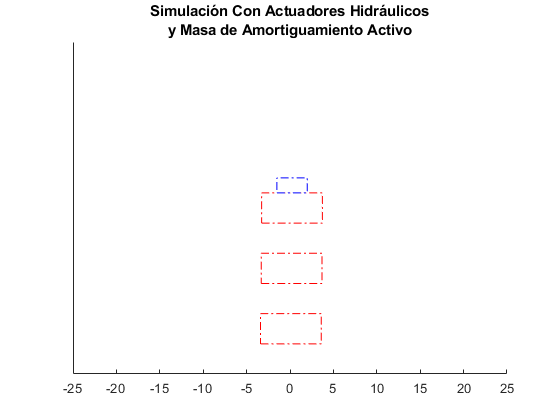

figure
anim_step = 1000;%Separación entre cada valor de animación
for t = 1:anim_step:size(pos,2)
    clf
    for i= 1:n

        offset = pos(i,t);

        temp_width = width;
        temp_height = height;
        temp_y = (i-1)*(sep+height);

        if i == n && ~mbkd(1) == 0
            temp_width = width/2;
            temp_height = height/2;
            temp_y = (i-1)*(sep+height)-sep;
            masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height], "LineStyle", "-.", "EdgeColor", "b");
        else 
            if r_theta(i) == 1
                 masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height], "LineStyle", "-.", "EdgeColor", "r");
            else 
                
                masa = rectangle("Position",[-temp_width/2+offset temp_y temp_width temp_height]);
            end

        end

        axis([-xlim xlim min_height max_height])
        yticks([])
        title(simTitle)
    end 
    drawnow update
end

## Funciones Auxiliares

function matrix = BK(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    for j = 1:n
        if j == i+1
            matrix(i,j) = -el(i+1);
        elseif j == i-1
            matrix(i,j) = -el(i);
        elseif i==j
            if  i == n && j == n
                matrix(i,j) = el(n);
            else
                matrix(i,j) = el(i)+el(i+1);
            end
        else
            matrix(i,j) = 0;
        end
    end
end
end

function matrix = MM(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    matrix(i,i) = el(i);

end
end

function matrix = BK_AMD(mat, el)
n = size(mat, 1);
matrix = [mat zeros(n,1); zeros(1,n-1) -el el];
end

function matrix = gamma_bar(n)

matrix = zeros(n);

for i = 1:n
   if i ~= n
        matrix(i, i) = -1;
        matrix(i, i+1) = 1; 
   else 
       matrix(i,i) = -1;
   end
end
end

function matrix = gamma_AMD(mat)
n = size(mat, 1);
matrix = [mat [zeros(n-1,1);-1];zeros(1,n) 1];

end

function matrix = MM_AMD(mat, el)

n = size(mat, 1);

matrix = [mat zeros(n, 1);zeros(1,n) el];

end


function BodeAnalysis(sys, n)
[mag, phase, wout] = bode(sys);
mag = 20*log10(squeeze(mag));
phase = squeeze(phase);

labels = cell(1,n);
for i = 1:n
    labels{1,i} = sprintf("x_%d(t)", i);
end

figure('Position', [100, 100, 1200, 1200])
plot(wout, mag)
hold on
idx = cell(1,n);
freq_res = [];

for i = 1:n
    [~, loc] = findpeaks(mag(i,:));
    idx{1, i} = loc;
    if i ~= 1
        freq_res = intersect(idx{1,i},idx{1,i-1});
    end
end

pks_sis = zeros(n,length(freq_res));


for i=1:length(freq_res)
    pks_sis(:,i) = mag(:,freq_res(i));
    freq_res(i) = wout(freq_res(i));
end


if ~isempty(freq_res)
    xline(freq_res, ":k")
    labels{1, n+1} = "LocalMax(H(\omega))";
end

hold off
title("Diagrama de Bode de Magnitudes")
xlim([0 100])
grid on
xlabel("Frecuencia (rad/s)")
ylabel("Magnitud (dB)")
legend(labels, "Location", "bestoutside")
if ~isempty(freq_res)
disp("Frecuencias de escalamiento máximo (rad/s):")
disp(freq_res)
disp("Escalamientos máximos (dB):")
for i=1:n
    fprintf("Para x_%d(t):\n", i)
    for j = 1:length(pks_sis(i,:))
        fprintf("%f ",double(pks_sis(i,j)))
    end
    fprintf("\n")
end
end

figure('Position', [100, 100, 1200, 1200])
plot(wout, phase)
title("Diagrama de Bode de Fases")
xlim([0 100])
xlabel("Frecuencia (rad/s)")
ylabel("Fase (grados)")
grid on
legend(labels{1,[1 2 3]},"Location", "bestoutside")
end
